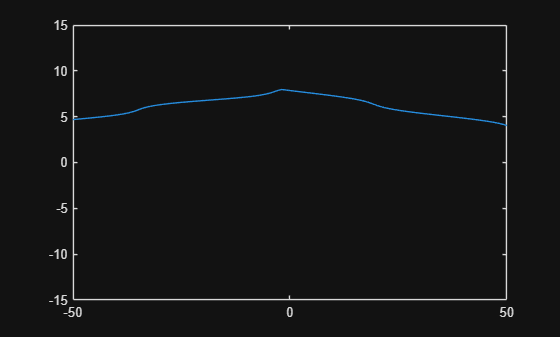

%{play around with z function (alter z trajectory), timespan (make very long), etc. --> try very rough oscillation%}
dtUfield = zeros(100, 2000);
dxUfield = zeros(100, 2000);
%Add back in initial data for particle to see what's what
%{try with dxUfield, compute a reimann sum, compute + plot field energy --> hopefully will oscillate getting smaller%}
for k = 1:500 %{we want intervals of 0.5 ideally, but that messes up tau%}, try 1:300

    tau = 0.5*k;

    alpha = 1;

    omega = 1;

    tcross = 1; %{come up with implicit definition, time where backwards light cone intersects particle world line; integral is 
    %{0 to tcross, think of it like 0 to t --> if particle is not in backwards light cone, = 0, otherwise do the other thing if the
    %{particle is  in the backwards light cone; check notes for this%}

    %{%}

    z = @(t) 3*sin(0.2*t); %play with frequency to be in phase with wave it sources

    %{besselsource = @(tt,s,z) alpha .* besselj(0, omega .* sqrt(tt.^2 - (s - z).^2));%}
    %{bessel(t, tt, s, z(tt))%}

    Usource = @(t, s) compute_Usource(t, s, z, alpha, omega);%{same as bessel if particle in light cone, %}

    slin = linspace(-250, 250, 2000);
    dx = slin(2) - slin(1);

    for i = 1:length(slin)
        solved_Usource(i) = Usource(tau, slin(i));
        Ufield(k, i) = solved_Usource(i);
    end
    
    if k == 1
        dtUfield(k, :) = 0;
    else
        dtUfield(k, :) = (Ufield(k, :) - Ufield(k - 1, :)) / 1;
    end

    for s=1:2000
        if s == 1
            dxUfield(k, s) = 0;
        else
            dxUfield(k, s) = (Ufield(k, s) - Ufield(k, s - 1)) / dx;
        end
    end

    plot(slin, solved_Usource)
    axis([-50 50 -15 15])
    saveas(gcf, ['Frame' num2str(k) '.png'])

end


% global energy, everywhere in space; also test how much is propogating
% from particle at c
E = zeros(100,1);

for k = 1:100
        for s = 1:2000
            if abs(z(0.5*k) - slin(s)) > 5
                E(k) = E(k) + dx * (dtUfield(k,s))^2 + dx * (omega^2)*(Ufield(k,s))^2 + dx * (dxUfield(k,s))^2;
            end
        end
end

time = linspace(0,250,100)

time =          0    2.5253    5.0505    7.5758   10.1010   12.6263   15.1515   17.6768   20.2020   22.7273   25.2525   27.7778   30.3030   32.8283   35.3535   37.8788   40.4040   42.9293   45.4545   47.9798   50.5051   53.0303   55.5556   58.0808   60.6061   63.1313   65.6566   68.1818   70.7071   73.2323   75.7576   78.2828   80.8081   83.3333   85.8586   88.3838   90.9091   93.4343   95.9596   98.4848  101.0101  103.5354  106.0606  108.5859  111.1111  113.6364  116.1616  118.6869  121.2121  123.7374


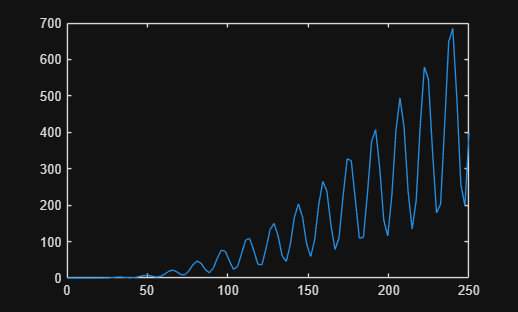

plot(time,E)

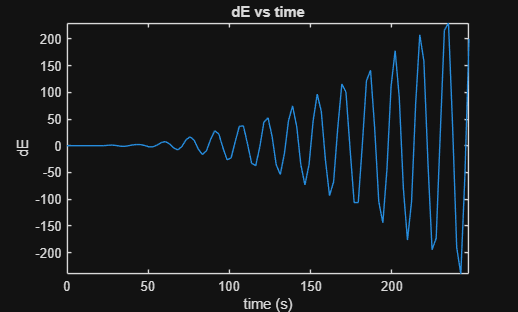


% 
% could be inc b/c 1) particle oscillating, we are giving energy to
% system/particle. But oscillation means giving energy AND slowing it down, so this may not be the reason 
% 2) hypothesis: because the waves propogate, we have oscillation in the y dir., but also propogation
% waves come back and hit the particle. More likely though; most of the
% wave goes of to infinity, never hits particle again. The radiation
% emitted by the particle goes off, but it still has energy. So field E
% inc, while particle E dec --> most of the wave leaves. Particle can't
% travel at c, so most of that energy is inaccesible to the particle. 

% also try plotting change in E vs t
dE = diff(E);
timeChange = time(1:end-1); % Adjust time vector for the derivative
figure;
plot(timeChange, dE);
xlabel('time (s)');
ylabel('dE');
title('dE vs time');
axis tight;


function U = compute_Usource(t, s, z, alpha, omega)
    
    if t^2 >= (s - z(t))^2
        U = integral(@(tt) besselCompute(t, tt, s, z(tt), alpha, omega), 0, t);
        %{introduce uInt --> integrand computed at many times between 0 and t
        %{introduce tlin, chop up integral, make uInt a vector where each component is
        %{integrand evaluated at each time of tlin (trapz function)%}
        %{alternate method for B array ^%}
    else
        U = 0;
    end
end

function B = besselCompute(t, tt, s, ztt, alpha, omega)
    n = length(tt);
    B = [];
    for i = 1:n
        if abs(t - tt(i)) > abs(s - ztt(i))
            B(i) = alpha .* besselj(0, omega .* sqrt(t.^2 - (s - ztt(i).^2)));
        else 
            B(i) = 0;
        end
    end
end

%get better numerical idea of what does the energy look like away from the
%particle